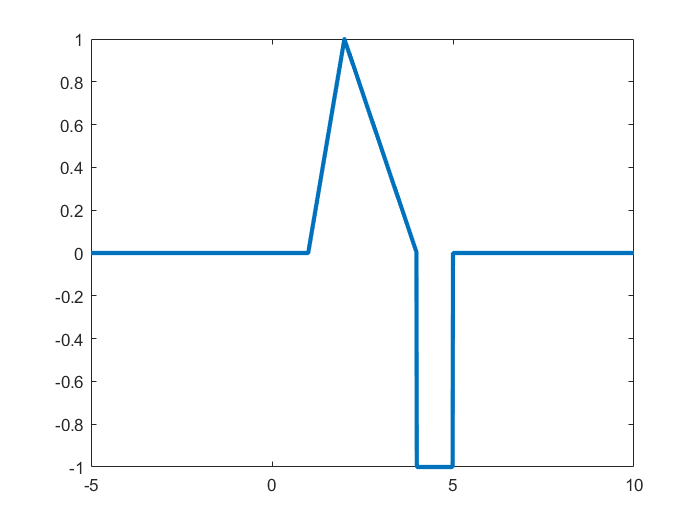

%Problem1
t=-5:0.01:10;
x1=f1(t);
plot(t,x1,'LineWidth',2.5);
print -r500 -djpeg plot1_1.jpg

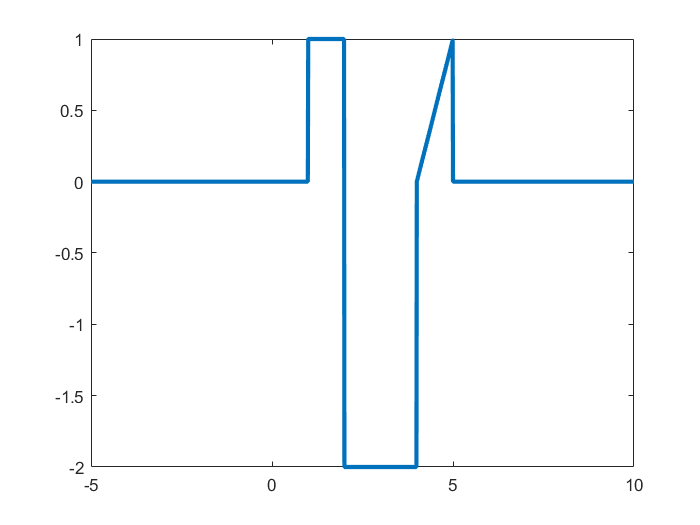

y1=f2(t);
plot(t,y1,'LineWidth',2.5);
print -r500 -djpeg plot1_5.jpg

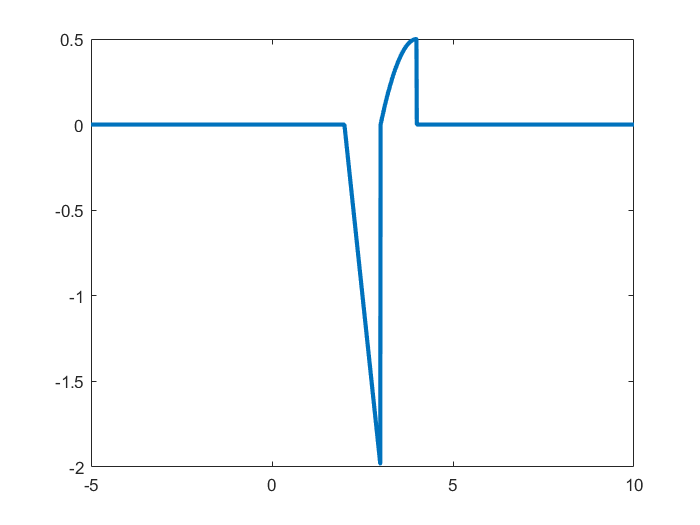

a=f1(t-1).* f2(t+1);
plot(t,a,'LineWidth',2.5);
print -r500 -djpeg plot1_2.jpg

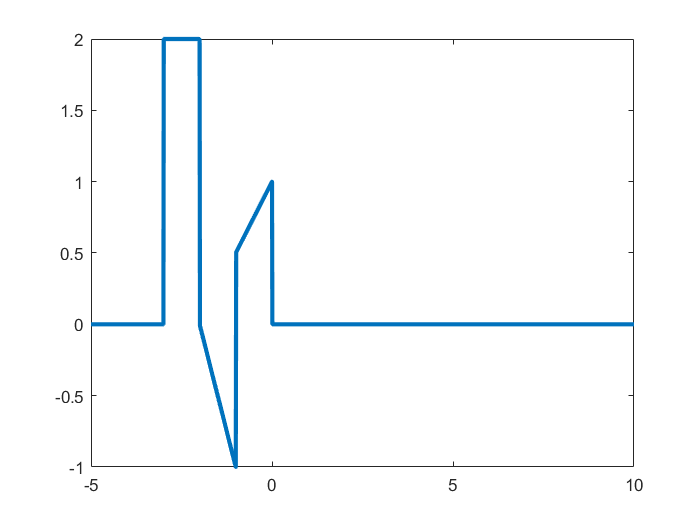

b=f1(2-t).* f2(1-t);
plot(t,b,'LineWidth',2.5);
print -r500 -djpeg plot1_3.jpg

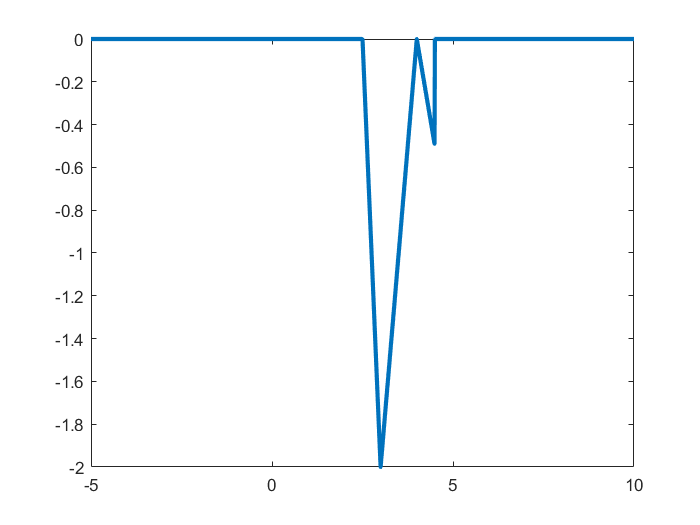

c=f1(2*t -4).* f2(t);
plot(t,c,'LineWidth',2.5);
print -r500 -djpeg plot1_4.jpg

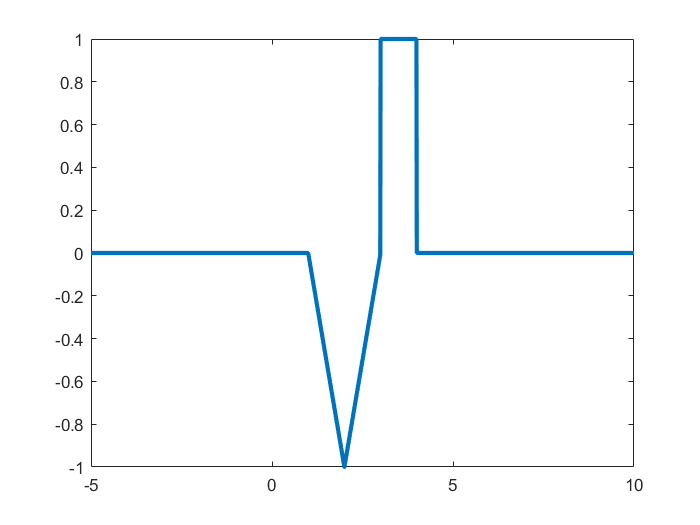





%Problem2
t=-5:0.01:10;
x2=f3(t);
plot(t,x2,'LineWidth',2.5);
print -r500 -djpeg plot2_1.jpg

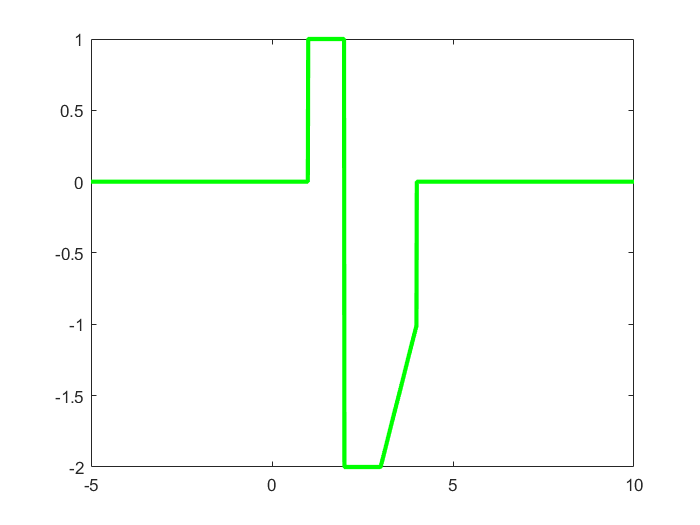

y2=f4(t);
plot(t,y2,'LineWidth',2.5,"Color",'g');
print -r500 -djpeg plot2_2.jpg

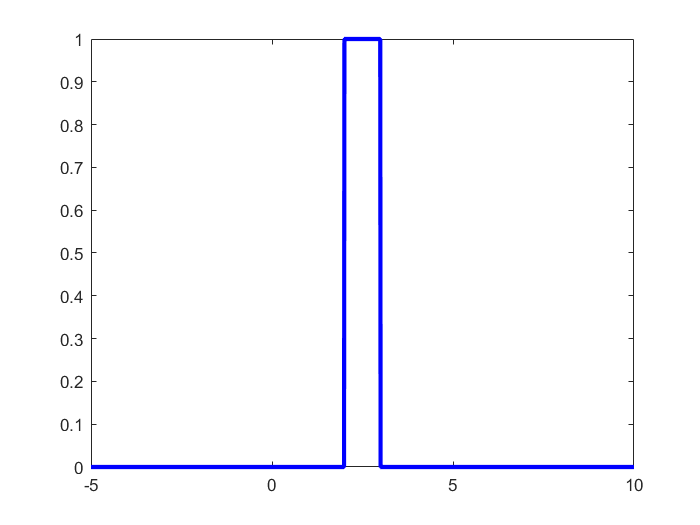

a=f3(t+1).* f4(t-1);
plot(t,a,'LineWidth',2.5,"Color",'b');
print -r500 -djpeg plot2_3.jpg

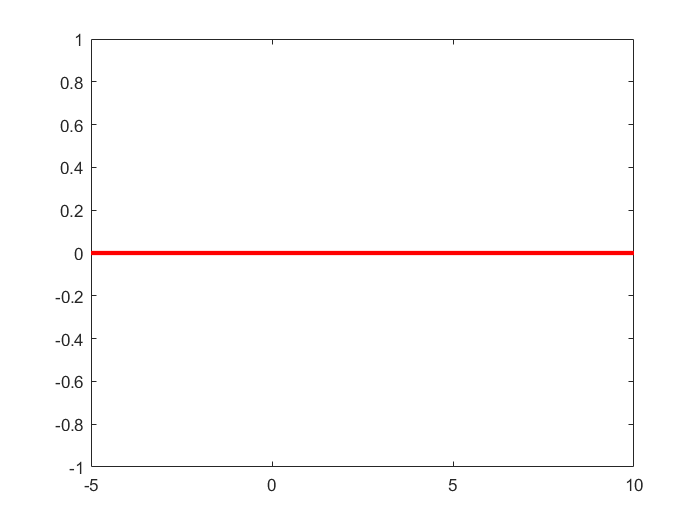

b=f3(2+t).* f4(-1-t);
plot(t,b,'LineWidth',2.5,"Color",'r');
print -r500 -djpeg plot2_4.jpg

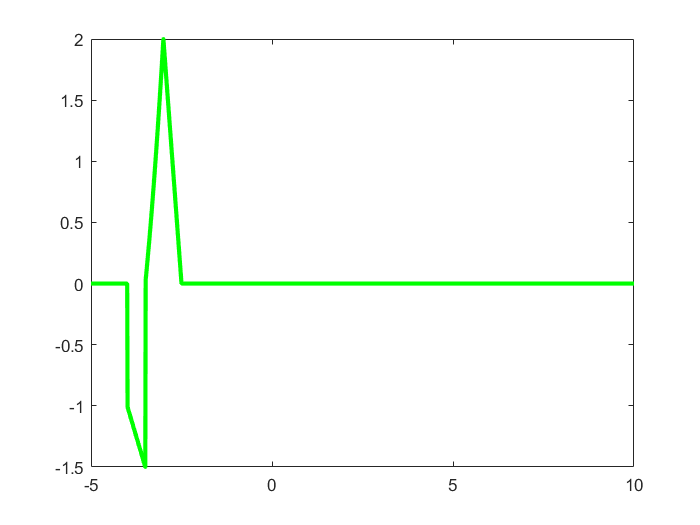

c=f3(-2*t -4).* f4(-t);
plot(t,c,'LineWidth',2.5,"Color",'g');
print -r500 -djpeg plot2_5.jpg

function x =f1(t) 
x=zeros(size(t));
x(t>=1 & t<2)= -1 +t(t>=1 & t<2);
x(t>=2 & t<4)= 2- (t(t>=2 & t<4)/2);
x(t>=4 & t<5)= -1;
x(t<1 | t>=5)= 0;
end

function y =f2(t)
y=zeros(size(t));
y(t>=1 & t<2)=1;
y(t>=2 & t<4)=-2;
y(t>=4 & t<5)= -4 +t(t>=4 & t<5);
y(t<1 | t>=5)=0;
end

function x =f3(t)
x=zeros(size(t));
x(t>=1 & t<2)= 1 -t(t>=1 & t<2);
x(t>=2 & t<3)= -3 +t(t>=2 & t<3);
x(t>=3 & t<4)= 1;
x(t<1 | t>=4)= 0;
end


function x =f4(t)
x=zeros(size(t));
x(t>=1 & t<2)= 1;
x(t>=2 & t<3)= -2;
x(t>=3 & t<4)= -5 +t(t>=3 & t<4);
x(t<1 | t>=4)= 0;
end




